%notation faithful to:
%Polyzou, W., & Bulut, F. (2013). Wavelet Methods in Field Theory. Few-Body Systems, 55(5-7), 561–566. doi:10.1007/s00601-013-0735-9 
%kek
  

% dB_K, kmax+1, xstep 
% % xstep is 1/(2^PREC + 1); 
[w,x] = wpfun('db3',5,15); 
fprintf("dbK\nsupport: [%d, %d] \npoints: %d\nxstep: %f",min(x), max(x), length(x), x(2))

dbK
support: [0, 5] 
points: 163842
xstep: 0.000031

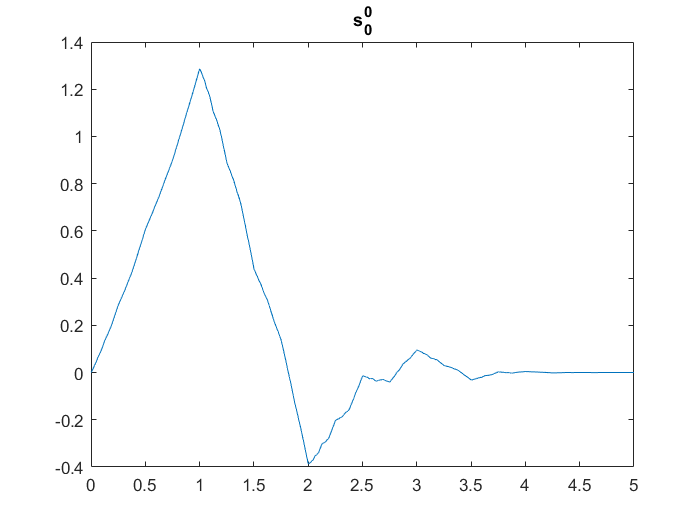

plot(x, w(1,:)); title('s^0_0'); 

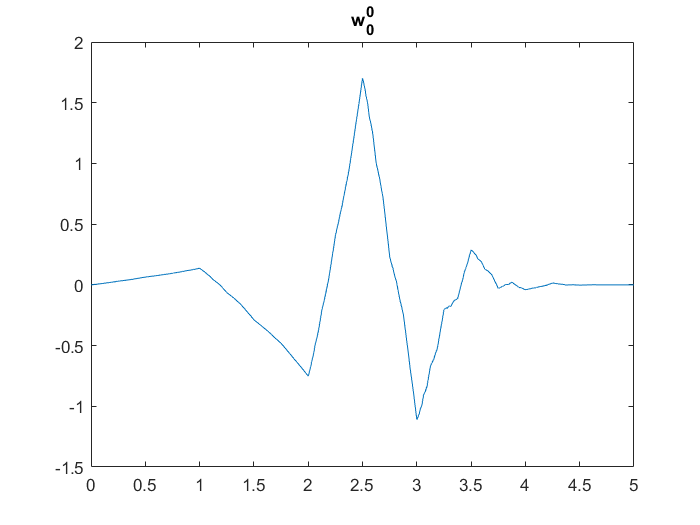

plot(x, w(2,:)); title('w^0_0'); 

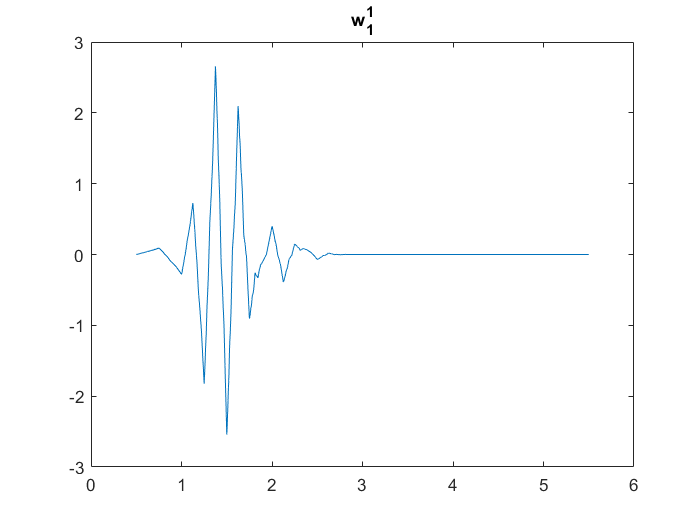

[wtest, xtest] = T(w(3,:),x);
[wtest, xtest] = D(wtest, xtest);
plot(xtest, wtest); title('w^1_1'); %1/2[n, 2K-1+n]

% s is the mother scaling fn PHI;  
% w is the mother wavelet fn PSI;
fprintf("<s|s> = %f",trapz(w(1,:).*w(1,:))*x(2));

<s|s> = 0.999994

fprintf("<w|w> = %f",trapz(w(2,:).*w(2,:))*x(2));

<w|w> = 0.999994

fprintf("<s|w> = %f",trapz(w(1,:).*w(2,:))*x(2));

<s|w> = -0.000014

function [Dw, Dx] = D(w,x)
    Dw = sqrt(2)*w;
    Dx = x/2;
    Dw = [Dw zeros(1, length(w))];
    Dx = wextend(1, 'asymw', Dx, length(x), 'r');
end

function [Tw, Tx] = T(w,x)
    Tw = w;
    Tx = x+1;
end